L5 Segona Part                                                                                            Marta Granero I Martí

## Exercici 2

Les funcions definides per les integrals

                        
$$J_0(x)\, =\,\displaystyle\frac{1}{\pi} \displaystyle \int_0^{\pi} \cos(x\cdot\sin\,t)\,dt\,,$$
                        
$$J_1(x)\, =\,\displaystyle\frac{1}{\pi} \displaystyle \int_0^{\pi} \cos(x\cdot\sin\,t -t)\,dt$$


són les funcions de bessel de primera espècie d'ordre 0 i d'ordre 1 respectivament. 

Per aquest exercici cal saber que una de les moltes relacions entre elles és 

                       
$$J_0^{\prime}(x) =-J_1(x)$$


i que en matlab **besselj(0,x****)** retorna el valor de 𝐽0(𝑥)  i **besselj(1,x)** calcula el valor de 𝐽1(x).

Enllaços

- [Función de Bessel (Wikipedia)](https://es.wikipedia.org/wiki/Funci%C3%B3n_de_Bessel)

- [Bessel Function of First Kind (Matlab)](https://es.mathworks.com/help/matlab/ref/besselj.html)

Problema:

**Objectiu** Estudiar l’error de trucament i l’error d’arroniment de la fórmula d’ordre ${\cal {O}}(h^2)$, definida per:

                                                    
$$F(h)=\displaystyle \frac {f(x_0+h)-f(x_0-h)}{2h}\,,\quad \quad (1)$$


en el càlcul de la derivada de la funció 𝐽0(𝑥) en 𝑥=2

1) Aproximeu 𝐽′0(2) fent ús de la fórmula 𝐹(ℎ) definida per (1), per a $h_k=2^{-k}$i $k=1,2,\dots5$.  Calculeu l’error absolut per cada una de les aproximacions obtingudes. 

clearvars
format shortG
syms t

x0 = 2;
ordre0 = besselj(0,x0);
ordre1 = besselj(1,x0);

taula = array2table([x0,ordre0,ordre1],"VariableNames",{'Punt', 'Funció bessel 1a espècie, ordre 0', 'Funció bessel 1a espècie, ordre 1'})

taula = 1×3 table
    Punt    Funció bessel 1a espècie, ordre 0    Funció bessel 1a espècie, ordre 1
    ____    _________________________________    _________________________________

     2                   0.22389                              0.57672             



fSimbolica(t) = besselj(0,t);
derivadafSimbolica(t) = -besselj(1,t);

valor = double(derivadafSimbolica(x0)); %cal posar double(....) per saber-ne el valor!

f = @(x) besselj(0,x);
F = @(x0,h) (f(x0 + h) - f(x0 - h))/(2*h);

h = 1./(2.^[1:5]);
for k = 1:5
    res(k,1) = h(k);
    res(k,2) = F(x0,h(k));
    res(k,3) = abs(res(k,2)-valor);
    res(k,4) = abs(res(k,2)-valor)/(sqrt(2));
    res(k,5) = abs(fix(-log10(2*abs(res(k,2)-valor))));
    res(k,6) = abs(fix(-log10(2*abs(res(k,2)-valor)/(sqrt(2)))));
end

taula = array2table(res,"VariableNames",{'hk', 'N1', 'Error Absolut', 'Error Relatiu', 'Decimals Correctes', 'Xifres Significatives'})

taula = 5×6 table
      hk          N1       Error Absolut    Error Relatiu    Decimals Correctes    Xifres Significatives
    _______    ________    _____________    _____________    __________________    _____________________

        0.5    -0.56021       0.016513         0.011677              1                       1          
       0.25    -0.57257      0.0041594        0.0029412              2                       2          
      0.125    -0.57568      0.0010418       0.00073668              2                       2          
     0.0625    -0.57646     0.00026058       0.00018426              3                       3          
    0.03125    -0.57666     6.5152e-05       4.6069e-05              3                       4          


2) Feu ús de la tècnica d’Extrapolació de Richardson d’ordre ${\cal {O}}(h^2)$ per obtenir una aproximació  de 𝐽′0(2) amb més decimals correctes. Calculeu l’error absolut per cada una de les aproximacions obtingudes. 

valor = double(derivadafSimbolica(x0));
x0 = 2;

%N1
%fórumles d'extrapolació de Richardson
N0 = @(h) (f(x0 + h) - f(x0 - h))/(2*h);
N1 = @(h) N0(h./2) + (N0(h./2) - N0(h))/(-1);
h = 1./(2.^[1:5]);
for k = 1:5
    structn1(k,1) = h(k);
    structn1(k,2) = N1(h(k));
    structn1(k,3) = abs(structn1(k,2)-valor);
    structn1(k,4) = structn1(k,3)/(sqrt(2));
    decimalsCorrectes1(k) = fix(-log10(2*abs(structn1(k,2)-valor)));
end

valorsTaula = structn1;
structn1 = array2table(valorsTaula, "VariableNames",{'hk', 'N1', 'Error Absolut', 'Error Relatiu'})

structn1 = 5×4 table
      hk          N1       Error Absolut    Error Relatiu
    _______    ________    _____________    _____________

        0.5    -0.56021       0.016513         0.011677  
       0.25    -0.57257      0.0041594        0.0029412  
      0.125    -0.57568      0.0010418       0.00073668  
     0.0625    -0.57646     0.00026058       0.00018426  
    0.03125    -0.57666     6.5152e-05       4.6069e-05  



%N2
%fórumla d'extrapolació de Richardson
N2 = @(h) N1(h./2) + (N1(h./2) - N1(h))/((4.^1)-1);
for k = 0:4
    i = k+1;
    if k > 0
        structn2(i,1) = N2(h(k));
        structn2(i,2) = abs(structn2(i,1)-valor);
        decimalsCorrectes2(i) = fix(-log10(2*structn2(i,2)));
    else
        structn2(i,:) = 0;
    end
end

valorsTaula = [valorsTaula(:,1:end-1) structn2];
structn2 = array2table(valorsTaula,"VariableNames",{'hk', 'N1', 'N2', 'Error Absolut', 'Error Relatiu'})

structn2 = 5×5 table
      hk          N1           N2        Error Absolut    Error Relatiu
    _______    ________    __________    _____________    _____________

        0.5    -0.56021      0.016513             0                 0  
       0.25    -0.57257     0.0041594      -0.57668         4.148e-05  
      0.125    -0.57568     0.0010418      -0.57672        2.6049e-06  
     0.0625    -0.57646    0.00026058      -0.57672          1.63e-07  
    0.03125    -0.57666    6.5152e-05      -0.57672        1.0191e-08  



%N3
%fórumla d'extrapolació de Richardson
N3 = @(h) N2(h./2) + (N2(h./2) - N2(h))/((4.^2)-1);
for k = -1:3
    i = k+2;
    if k > 0
        structn3(i,1) = N3(h(k));
        structn3(i,2) = abs(structn3(i,1)-valor);
        decimalsCorrectes3(i) = fix(-log10(2*structn3(i,2)));
    else
        structn3(i,:) = 0;
    end
end

valorsTaula = [valorsTaula(:,1:end-1) structn3];
structn3 = array2table(valorsTaula,"VariableNames",{'hk', 'N1', 'N2', 'N3', 'Error Abolut', 'Error Relatiu'})

structn3 = 5×6 table
      hk          N1           N2           N3       Error Abolut    Error Relatiu
    _______    ________    __________    ________    ____________    _____________

        0.5    -0.56021      0.016513           0             0                0  
       0.25    -0.57257     0.0041594    -0.57668             0                0  
      0.125    -0.57568     0.0010418    -0.57672      -0.57672       1.3212e-08  
     0.0625    -0.57646    0.00026058    -0.57672      -0.57672       2.0707e-10  
    0.03125    -0.57666    6.5152e-05    -0.57672      -0.57672       3.2385e-12  



%N4
%fórumla d'extrapolació de Richardson
N4 = @(h) N3(h./2) + (N3(h./2) - N3(h))/((4.^3)-1);
for k = -2:2
    i = k+3;
    if k > 0
        structn4(i,1) = N4(h(k));
        structn4(i,2) = abs(structn4(i,1)-valor);
        decimalsCorrectes4(i) = fix(-log10(2*structn4(i,2)));
    else
        structn4(i,:) = 0;
    end
end

valorsTaula = [valorsTaula(:,1:end-1) structn4];
structn4 = array2table(valorsTaula,"VariableNames",{'hk', 'N1', 'N2', 'N3', 'N4', 'Error Absolut', 'Error Relatiu'})

structn4 = 5×7 table
      hk          N1           N2           N3          N4       Error Absolut    Error Relatiu
    _______    ________    __________    ________    ________    _____________    _____________

        0.5    -0.56021      0.016513           0           0             0                 0  
       0.25    -0.57257     0.0041594    -0.57668           0             0                 0  
      0.125    -0.57568     0.0010418    -0.57672    -0.57672             0                 0  
     0.0625    -0.57646    0.00026058    -0.57672    -0.57672      -0.57672        6.3649e-13  
    0.03125    -0.57666    6.5152e-05    -0.57672    -0.57672      -0.57672        3.1086e-15  


3) Presenteu els resultats dels dos apartats previs en una mateixa taula (T1). 

T1 = array2table(valorsTaula,"VariableNames",{'hk', 'N1', 'N2', 'N3', 'N4', 'Error Absolut', 'Error Relatiu'})

T1 = 5×7 table
      hk          N1           N2           N3          N4       Error Absolut    Error Relatiu
    _______    ________    __________    ________    ________    _____________    _____________

        0.5    -0.56021      0.016513           0           0             0                 0  
       0.25    -0.57257     0.0041594    -0.57668           0             0                 0  
      0.125    -0.57568     0.0010418    -0.57672    -0.57672             0                 0  
     0.0625    -0.57646    0.00026058    -0.57672    -0.57672      -0.57672        6.3649e-13  
    0.03125    -0.57666    6.5152e-05    -0.57672    -0.57672      -0.57672        3.1086e-15  


4) Representeu les xifres decimals correctes en una gràfica, amb $k=1,2,\dots5$ a l’eix d’abscises. Quantes xifres decimals correctes s’obtenen en cada cas? Argumenta la teva resposta.

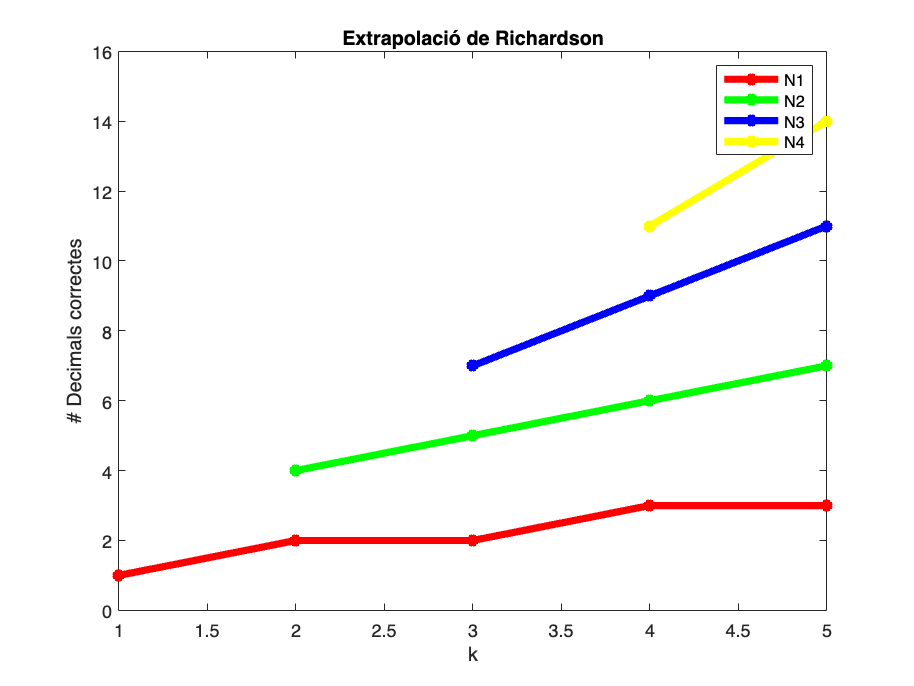

plot([1:5], decimalsCorrectes1, 'r-*', [2:5], decimalsCorrectes2(2:end), 'g-*', [3:5], decimalsCorrectes3(3:end), 'b-*', [4:5], decimalsCorrectes4(4:end), 'y-*', 'LineWidth', 4);
title("Extrapolació de Richardson");
legend('N1','N2','N3','N4');
xlabel("k");
ylabel("# Decimals correctes");
xlim([1 5])
ylim([0 16])